clear all
close all
clc

m = 1000:2000:15000;
m(1)=100; m(2)=300; m(3)=600; m(4)=1500; m(5)=5000;
n(1)=5; n(2)=10; n(3)=15; n(4)=40; n(5)=90;
K = sqrt(m/2);
P = 1:3:35;
[Pr, Pc] = size(P);
scaleup = ones(Pr, Pc ,5,5);



for k=1:5

    for z=1:5
    
        for i=1:size(P,2)
        
            time_oneP = m(z) * (3*n(k)*K + K + n(k) + 1) + K*(2+n(k));
            time_multP = (m(z)/P(i) * (3*n(k)*K + K + n(k) + 1) + K * (2*P(i) + n(k)))*P(i);
            scaleup(1,i,z,k) = time_oneP / time_multP;
        
        end
    
    end

end


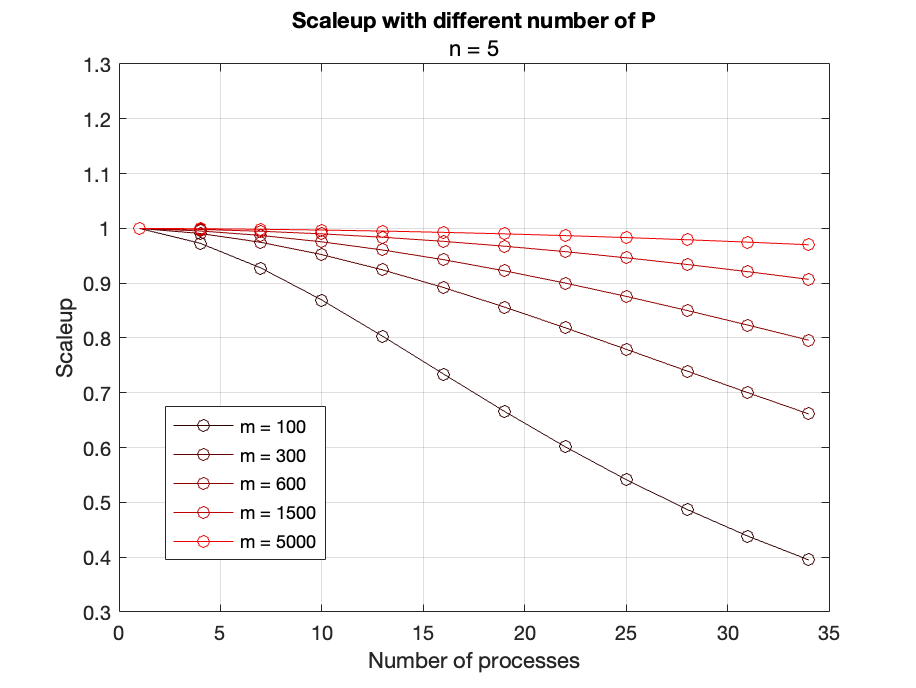

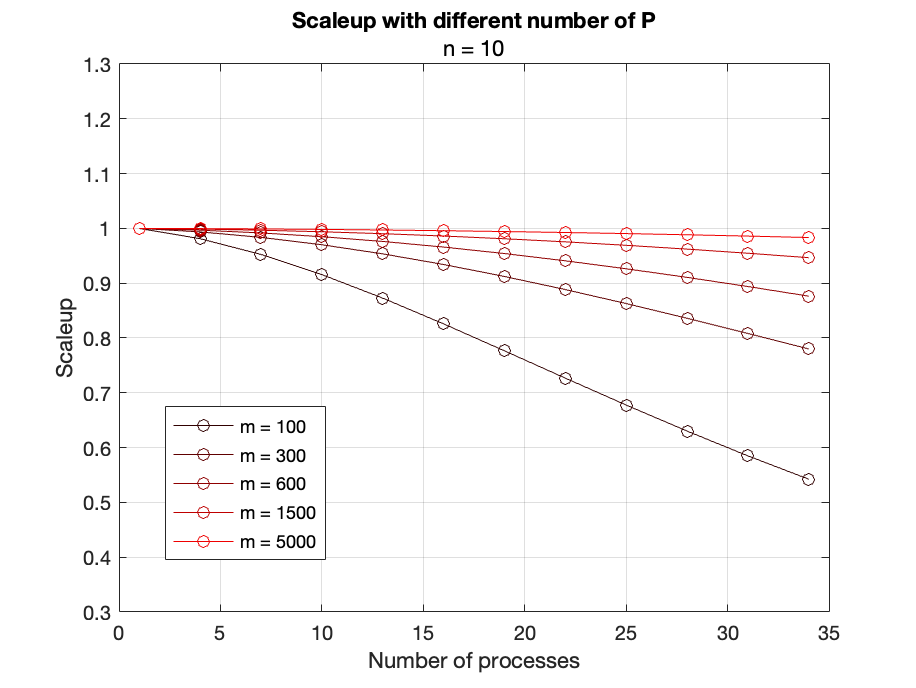

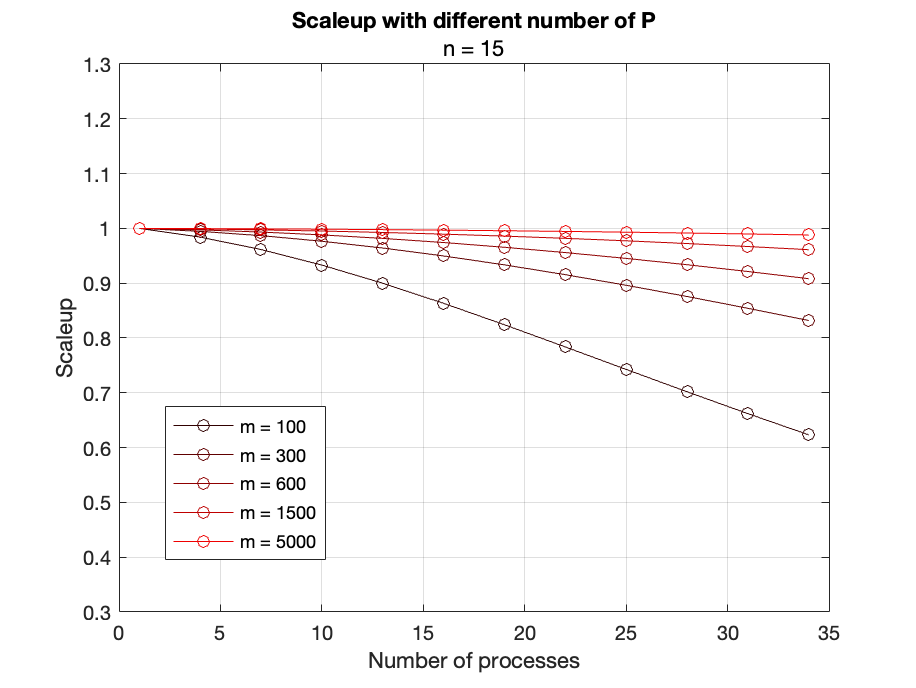

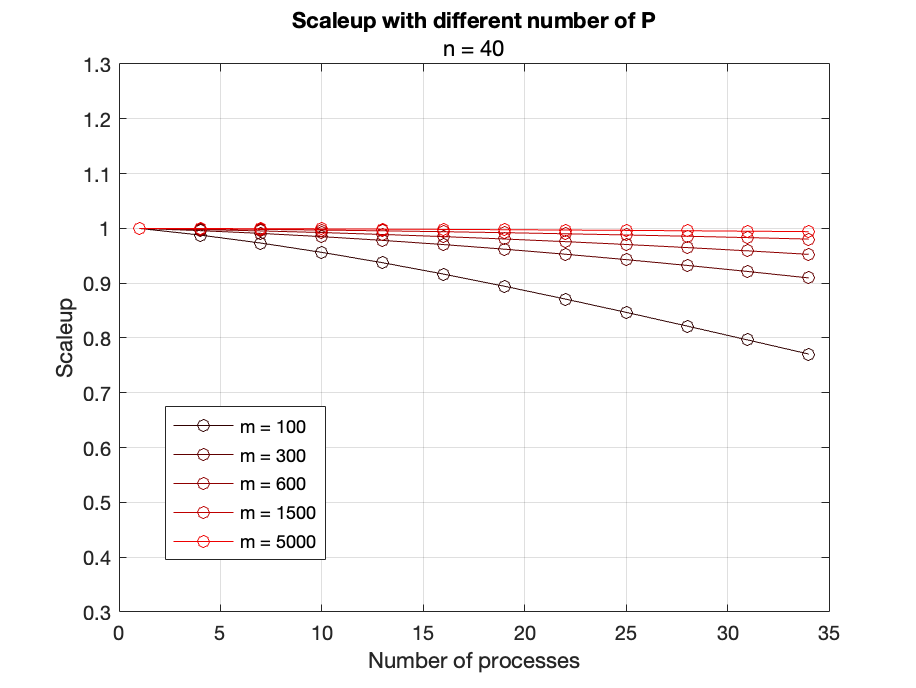

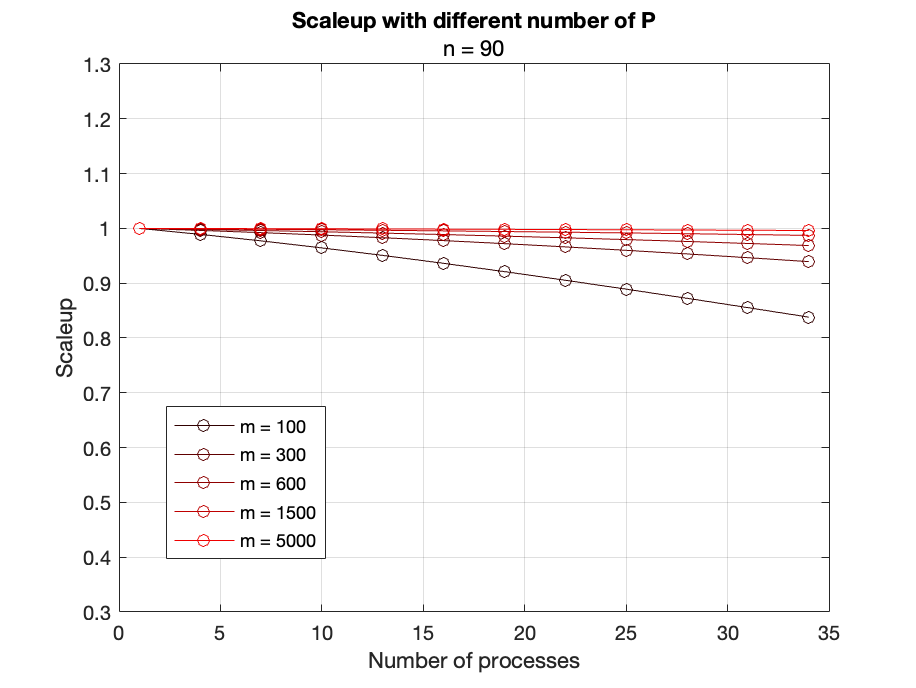

for k=1:5
    for z=1:5
        plot(P,scaleup(1,:,z,k),'b-o',Color=[(z*3)/(5*3+1),0,0]);
        ylim([0.3,1.3]);
        hold on
    end
    hold off
    title('Scaleup with different number of P');
    subtitle(sprintf('n = %d', n(k)));
    grid on;
    xlabel('Number of processes');
    ylabel('Scaleup');
    
    legend("Position",[0.1814,0.18688,0.17249,0.22091])
    legend('m = 100', 'm = 300' , 'm = 600', 'm = 1500' , 'm = 5000');
    figure()
    

end